Aula 05

Interpolação polinomial

Parte 1

Exercício dos apontamentos de interpolação polinomial

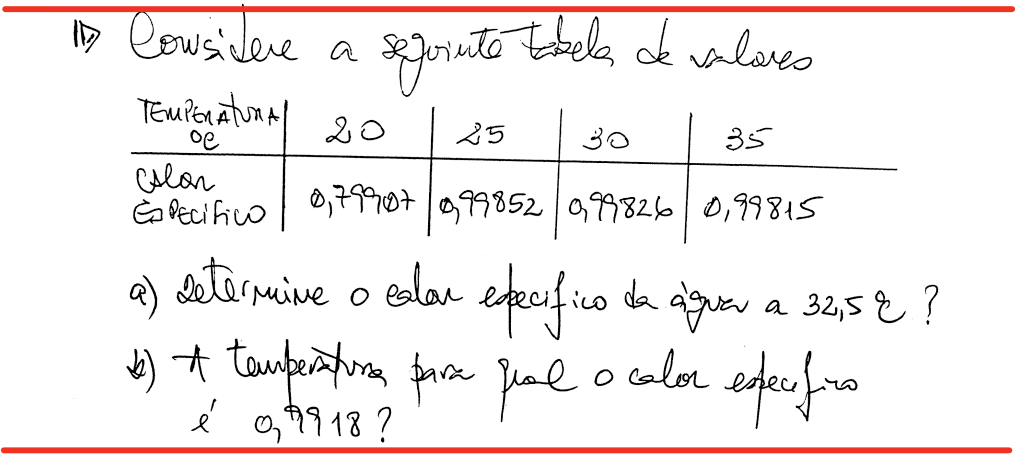

clear

% dados
x = [20 25 30 35];
y = [0.79907 0.99852 0.99826 0.99815];

%teste logico para verificar se os vetores tem o mesmo numero de elementos

n = length(x);
n == length(y)

ans = logical
   1





% alínea (a)
% coeficientes do único polinómio interpolador
coefs = polyfit(x,y,n-1)

coefs =     0.0003   -0.0240    0.7126   -5.9930


%calcular o vvalor do polinomio usando o polyval
xi=32.5;
yi = polyval(coefs,xi) %estimativa do calor especifico para t=32.5

yi = 0.9857


% outras opções
% usando a função "interp1(x,y,xi,method)"
interp1(x,y,xi,"linear")

ans = 0.9982

interp1(x,y,xi,"cubic")

ans = 0.9982

interp1(x,y,xi,"spline")

ans = 0.9857


% alínea (b)
% interpolação inversa
%trocar os papeis de x e y
format longG
coefs = polyfit(y,x,n-1)

coefs =           356498586.144606         -996813242.781472          924342755.795142         -284027918.403938



yi=0.9918;

xi = polyval(coefs,yi)

xi =           3132.72971642017



interp1(y,x,yi,"linear")

ans =           34.5215491259795


%interp1(y,x,yi,"cubic") apenas para quando os valores estao separados a
%mesma distancia
interp1(y,x,yi,"spline")

ans =           3132.72984223813



format default







